# Problem Solving Session 3

03/29/2021

## nth Root Using Newton

Find the cube root of $13$, i.e., $\sqrt[3]{13}$.

a = 13;
n = 3;
r = nthroot(a,n); % using MATLAB's built-in function

niter = 6;
x = zeros(niter, 1);
err = zeros(size(x));
x(1) = 2;
err(1) = abs(x(1)-r);

for k = 1:niter-1
    x(k+1) = (n-1)/n*x(k) + a/(n*x(k)^(n-1));
    err(k+1) = abs(x(k+1)-r);
end

format long
x, err

x =    2.000000000000000
   2.416666666666667
   2.353084951776985
   2.351335989273735
   2.351334687721478
   2.351334687720757


err =    0.351334687720757
   0.065331978945909
   0.001750264056228
   0.000001301552977
   0.000000000000721
                   0


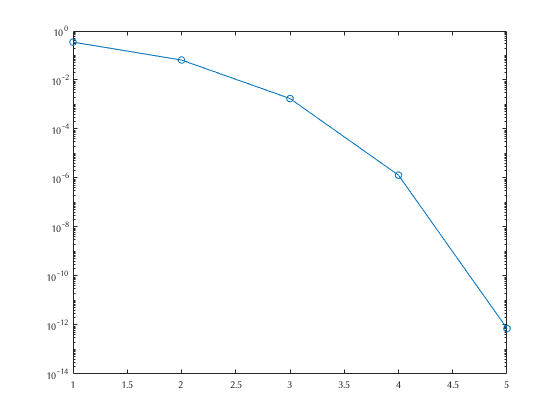


clf
semilogy(err, 'o-')